# Concatenated Model

## Load the appropriate models

initCobraToolbox()



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2021
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.24.3).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

changeCobraSolver('gurobi')


 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > The compatibility can only be evaluated on the following mac OS versions: macOS 10.12, macOS 10.13.
 > The solver compatibility is not tested with MATLAB R2020a.


ans = logical
   1



% load WT model
load('Model_iJB785.mat');
load('Model_iJB785.mat', 'iJB785');
model.WT = iJB785;

% load SBP reaction constricted model
model.SBP0 = changeRxnBounds(model.WT, 'SBP', 0, 'b')

model = struct with fields:
          WT: [1×1 struct]
        SBP0: [1×1 struct]
       SBPu1: [1×1 struct]
       SBPu5: [1×1 struct]
       SBPl5: [1×1 struct]
         SBP: [1×1 struct]
        rTCA: [1×1 struct]
         gly: [1×1 struct]
       TALA8: [1×1 struct]
       TALA5: [1×1 struct]
        FBP8: [1×1 struct]
        FBP5: [1×1 struct]
    TALAFBP8: [1×1 struct]
    TALAFBP5: [1×1 struct]



% load models with different upper bounds for SBP flux
model.SBPu1 = changeRxnBounds(model.WT, 'SBP', 1, 'u');
model.SBPu5 = changeRxnBounds(model.WT, 'SBP', 0.5, 'u');
model.SBPl5 = changeRxnBounds(model.WT, 'SBP', 0.5, 'l');
model.SBP = changeRxnBounds(model.WT, 'SBP', 0, 'b');


% load rTCA model
load('edited_Model_iJB785.mat', 'iJB785');
model.rTCA = iJB785;

% load glycoaldehyde model
load('editedGlycolaldehydeAddition_gurobi.mat', 'iJB785');
model.gly = iJB785;

% create model with TALA overexpression & SBP deletion
model.TALA8 = changeRxnBounds(model.WT, 'SBP', 0, 'b');
model.TALA8 = changeRxnBounds(model.TALA8, 'TALA', -800, 'u')

model = struct with fields:
          WT: [1×1 struct]
        SBP0: [1×1 struct]
       SBPu1: [1×1 struct]
       SBPu5: [1×1 struct]
       SBPl5: [1×1 struct]
         SBP: [1×1 struct]
        rTCA: [1×1 struct]
         gly: [1×1 struct]
       TALA8: [1×1 struct]
       TALA5: [1×1 struct]
        FBP8: [1×1 struct]
        FBP5: [1×1 struct]
    TALAFBP8: [1×1 struct]
    TALAFBP5: [1×1 struct]


model.TALA5 = changeRxnBounds(model.WT, 'SBP', 0, 'b');
model.TALA5 = changeRxnBounds(model.TALA5, 'TALA', -500, 'u');

% create model with just FBP overexpression & SBP deletion
model.FBP8 = changeRxnBounds(model.WT, 'SBP', 0, 'b');
model.FBP8 = changeRxnBounds(model.FBP8, 'FBP', 800, 'l');
model.FBP5 = changeRxnBounds(model.WT, 'SBP', 0, 'b');
model.FBP5 = changeRxnBounds(model.FBP5, 'FBP', 500, 'l');

% create model with both TALA & FBP overexpression & SBP deletion
model.TALAFBP8 = changeRxnBounds(model.FBP8, 'TALA', -800, 'u');
model.TALAFBP5 = changeRxnBounds(model.FBP5, 'TALA', -500, 'u');


## Prep Models based on Broddrick Expectations for Growth Curves for TALA no constraints

model1 = model.gly;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Suggested non-network constraints from supplemental material
%1) couple flux between transketolase and phophoketolase to make PDH essential
model1.S(end+1,:) = 0;
model1.b(end+1) = 0; % 0 indicates no concentration change
model1.mets{end+1} = 'pkcc'; % adds last element in metabolites as pkcc
model1.metNames{end+1} = 'Transketolase/Phosphoketolase coupling constraint';
model1.csense(end+1) = 'G'; % such that 0.01*vTKT2 - vPKETF(or PKETX) >= 0 (indicates b vector is lower bound constraint for metabolites)
tkt2 = findRxnIDs(model1,'TKT2');
pkf = findRxnIDs(model1,'PKETF');
pkx = findRxnIDs(model1,'PKETX');
model1.S(end,pkf) = -1; % make the element in the last row, column pkf = -1
model1.S(end,pkx) = -1;
model1.S(end,tkt2) = -0.01;
model1 = addDemandReaction(model1,'pkcc'); %opposite of sink- pkcc considered a demand reaction
%2) make VPAMTr irreversible towards alanine, forces use of GLUSfx
vpamt = findRxnIDs(model1,'VPAMTr'); %finds the reaction VPAMTr & makes it only 1 direction
model1.lb(vpamt)=-1000;
model1.ub(vpamt)=0;
%3) transhydrogenase carries no flux
model1 = changeRxnBounds(model1,'NADTRHD',0,'b');
%4) set transaldolase as irreversible towards e4p/f6p
% model1 = changeRxnBounds(model1,'TALA',0,'l');
%5) ornitine transaminase carries no flux; based on essentiality of proline and asparagine biosynthetic pathways
model1 = changeRxnBounds(model1,'ORNTA',0,'b');
%6) CYOOum carries no flux
model1 = changeRxnBounds(model1,'CYOOum',0,'b');
%7) LDH_D irrev way from pyruvate
model1 = changeRxnBounds(model1,'LDH_D',0,'u');
%8) SBPase carries no flux
%model1 = changeRxnBounds(model1, 'SBP', 0, 'b')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Set media to BG-11
% BG-11 at 100mL total volume
% # media BG-11
% # BG-11
% # NaNO3:   17.6 mM     MgSO4:         0.3 mM
% # K2HPO4:  0.23 mM     citrate:       0.031 mM
% # CaCl2:   0.24 mM     FeNH4 citrate: 0.024 mM citrate, 0.031 mM ammonia,
%                                       0.010 mM Fe3 (based on 9% amm, 16%
%                                       Fe and 75% citrate
% # Na2EDTA: 0.0027 mM   Na2CO3:        0.19 mM
% # Trace solution: 1000x
% # H3BO3:   46 mM       MnCl2:         9mM
% # ZnSO4:   0.77 mM     Na2MoO4:       1.6mM
% # CuSO4:   0.3 mM      Co(NO3)2:      0.17 mM
% open up all exchange reaction so that products can be released
ex_r = strmatch('EX_',model1.rxns); %finds indices in matrix model1.rxns where starts with EX_
for i = 1:length(ex_r) %for each exchange reaction in model, force forward
    model1.lb(ex_r(i)) = 0;
    model1.ub(ex_r(i)) = 1000;
end
%the unit for bound is mol?
rxns = {'EX_h2o_e';'EX_o2_e';'EX_co2_e';'EX_cobalt2_e';'EX_zn2_e';'EX_so4_e';'EX_ca2_e';'EX_nh4_e';'EX_mn2_e';'EX_hco3_e';'EX_mg2_e';'EX_cu2_e';'EX_k_e';'EX_no3_e';'EX_fe3_e';'EX_mobd_e';'EX_na1_e';'EX_h_e';'EX_pi_e'};
bound = [-1000;-1000;-1000;-1.70000000000000e-05;-7.70000000000000e-05;-0.0300000000000000;-0.0240000000000000;-0.00310000000000000;-0.000900000000000000;-0.0190000000000000;-0.0300000000000000;-3.00000000000000e-05;-0.0460000000000000;-1.76000000000000;-0.00200000000000000;-0.000160000000000000;-1.79854000000000;-1000;-0.0230000000000000];
for i = 1:length(rxns)
    index = strmatch(rxns{i},model1.rxns,'exact'); %looks for rxns{i} exactly in model1.rxns
    model1.lb(index)=bound(i); %for each reaction, sets appropriate bound in its matrix place
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Photon constraints
% This file assigns the optical absorption cross-section, the chlorophyll a 
% composition of the biomass and the spectral irradiance.


% a is a*(bin) = optical absorption cross-section of the 20nm bin normalized to 
% mg chl a; units: cm^2/mg ChlA

oabxc = [460.700000000000,598.900000000000,565.500000000000,415.200000000000,352.900000000000,277.700000000000,157.300000000000,124.300000000000,146.800000000000,193.200000000000,263.700000000000,335.800000000000,269,303.600000000000,267.700000000000];
% mean = [460.700000000000,598.900000000000,565.500000000000,415.200000000000,352.900000000000,277.700000000000,157.300000000000,124.300000000000,146.800000000000,193.200000000000,263.700000000000,335.800000000000,269,303.600000000000,267.700000000000]
% ub95 = [495.500000000000,645.300000000000,608.300000000000,446.400000000000,379.300000000000,298.600000000000,169.300000000000,133.800000000000,157.700000000000,207.900000000000,285.200000000000,364,291.200000000000,328,289.300000000000]
% lb95 = [425.900000000000,552.500000000000,522.600000000000,384,326.400000000000,256.800000000000,145.300000000000,114.900000000000,135.900000000000,178.500000000000,242.300000000000,307.600000000000,246.900000000000,279.100000000000,246]
bins = [410;430;450;470;490;510;530;550;570;590;610;630;650;670;690];
% Get chla composition of the biomass in mg Chla/1000 mg biomass
% Chla as a percent of pigments
r = strmatch('BM_PIGMENTS',model1.rxns,'exact'); %r is index where BM_Pigments are in model1.rxns
m1 = strmatch('cholphya_c',model1.mets,'exact'); %m1 is index where cholphya_c are in model1.mets
[~,~,chla_stoich] = find(model1.S(m1,r)); %tilde is placeholder so find the elements in index with pigements for chlorophyll a but only place in 3rd column of row
chla = chla_stoich*893.4861/1000;% umol chla * umol/mg
% get pigments as a percent of biomass
r = strmatch('BOF',model1.rxns,'exact');
m2 = strmatch('bm_pigm_c',model1.mets,'exact');
[~,~,pigm] = find(model1.S(m2,r));
a = oabxc.*(chla*pigm);

% Relative spectral distribution of Octron 741 4100K 32W light source
relArea = [0.0334,0.0931,0.0427,0.0400,0.0750,0.0238,0.0424,0.2089,0.0675,0.1089,0.1601,0.0595,0.0213,0.0141,0.0093];
conv = 60*60/10000; %converts photon flux from umol/(m2*s) to umol/(cm2*h)
irrad = [68]; %irradiance in uE
str_to_print = strcat('Irradiance: ',num2str(irrad));
pfd = relArea.*(conv);
% photon absorbtion rate = a*(bin) x photon flux density
pha = a.*pfd; %umol photons/(mgDW*h)
% xphr are exchange photon reactions
xphr = {'EX_photon410_e', 'EX_photon430_e', 'EX_photon450_e', 'EX_photon470_e', 'EX_photon490_e', 'EX_photon510_e', 'EX_photon530_e', 'EX_photon550_e', 'EX_photon570_e', 'EX_photon590_e', 'EX_photon610_e', 'EX_photon630_e', 'EX_photon650_e', 'EX_photon670_e', 'EX_photon690_e'};
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Additional initializing values
% 2% of the culture volume in each ring
vol = [2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2];
% initial mgDW of inoculation in a 100mL flask
iDW = 7.1; 
%area used for photon delivery
xsec = 54.3;
% relative volume
rv = vol./100;
results = []; %initialize the results variable
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Calculates self-shading growth rate
for z = 1:length(irrad) % If more than one irradiance is to be simulated
    % Reset media for new simulation at new irradiance
    ex_r = strmatch('EX_',model1.rxns); %ex_r = index of all exchange reactions in model1
    for i = 1:length(ex_r) % for each exchange reaction, force forward
        model1.lb(ex_r(i)) = 0;
        model1.ub(ex_r(i)) = 1000000;
    end
    rxns = {'EX_h2o_e';'EX_o2_e';'EX_co2_e';'EX_cobalt2_e';'EX_zn2_e';'EX_so4_e';'EX_ca2_e';'EX_nh4_e';'EX_mn2_e';'EX_hco3_e';'EX_mg2_e';'EX_cu2_e';'EX_k_e';'EX_no3_e';'EX_fe3_e';'EX_mobd_e';'EX_na1_e';'EX_h_e';'EX_pi_e'};
    bound = [-1000;-1000;-1000;-1.70000000000000e-05;-7.70000000000000e-05;-0.0300000000000000;-0.0240000000000000;-0.00310000000000000;-0.000900000000000000;-0.0190000000000000;-0.0300000000000000;-3.00000000000000e-05;-0.0460000000000000;-1.76000000000000;-0.00200000000000000;-0.000160000000000000;-1.79854000000000;-1000;-0.0230000000000000];
    bound = bound*1000;
    for i = 1:length(model1.rxns)
        model1.lb(i) = model1.lb(i)*1000;
        model1.ub(i) = model1.ub(i)*1000;
    end
    %for each reaction in previously stated, replace bounds with specified ones
    for i = 1:length(rxns)
        index = strmatch(rxns{i},model1.rxns,'exact');
        model1.lb(index)=bound(i);
    end
    %initialize matrix for solution.x and solution.f
    fluxMat10 = [];
    %TALAMat10 = [];
    % set interval spacing in hours
    hours = linspace(1,400,400); %1-240 hr, measurement each hour
    gDW = iDW; %Set the initial biomass at inoculation
    plot_me = []; %initialize variable for plotting
    plot_me = [plot_me;iDW]; %create vector with plotting variable and new column of initial biomass 
    % initialize variables for output
    biomass = []; % biomass production over the simulation interval
    biomass = [biomass;iDW]; %create vector with biomass & new column of initial biomass

    for i = 1:length(hours)
        h = 1; %Time interval of simulation in hours
        tpbm = 0; %initialize a variable to collect the biomass from each slice
        tppi = 0; %initialize a variable to collect the phosphate uptake from each slice
        atten = zeros(1,length(xphr)); % initializes the variable to take light attenuation into account
            % creates 1 row of zeros (length of # photon reactions)
        %for each slice, being 1-length of volume
        for s = 1:length(vol)
            sDW = rv(s)*gDW; %sets proportion of biomass in the current slice (gDW + iDW for starting)
            spha = pha.*(sDW*irrad(z)*h); %sets photon absorption rate for the slice (proportion biomass*hour*z)
            sphd = pfd.*(xsec*irrad(z)*h); %sets photon delivery rate for the slice 
            
            % adjust for attenuation
            for at = 1:length(sphd)
                initial = sphd(at);
                atvalue = atten(at);
                sphd(at) = sphd(at)+atten(at);
            end

            % set all negative values to 0 photon delivery
            for si = 1:length(sphd)
                in = sphd(si);
                if in < 0
                    sphd(si) = 0;
                end
            end

            %General constraints
            
            %Maintenance
            model1 = changeRxnBounds(model1,'NGAM',(0.071*h*sDW),'l'); %non-growth associated maintenance
            %Carbon uptake (non-growth associated maitnenance lower bounds
            %increases according to biomass increase by the hour)
            cup = -2.0*sDW*h; %CO2 uptake, arbitrary, high value (sDW: prop biomass*hour)
            bicup = -2.0*sDW*h; % Bicarb uptake, arbitrary, high value
            model1 = changeRxnBounds(model1,'EX_co2_e',cup,'l'); %have lower bound of exchange CO2 have high value based on biomass
            model1 = changeRxnBounds(model1,'EX_hco3_e',bicup,'l'); %have lower bound of exchange bicarb have high value based on biomass
            %O2 evolution, P(I)=Ps(1-e^(-a*I/Ps))*e^(-BI/Ps) Platt fitting of
            %O2 evolution; Ps = 153, a = 1.42, B = 9.3E-14, I = irradiance
            o2rate =  153*(1-exp(-1.42*irrad(z)/153))*(exp(-9.3E-14*irrad(z)/153));
            o2evo = o2rate*sDW*h*(10/1000); %Chl a is 1% of biomass
            model1 = changeRxnBounds(model1,'EX_o2_e',o2evo,'u'); %set upper limit of O2evo based on biomass levels
            % PSII max rate = 700umol O2/(mgChlA*hr)
            psii_max = 7*sDW*h;
            model1 = changeRxnBounds(model1,'PSIIum',psii_max,'u'); %set upper limit of PSII based on biomass levels
            % Set photon exchange bounds
            for r = 1:length(xphr) %for each photon based reaction

                if spha(r) < (sphd(r)) %if photon abs rate < photon delivery rate at photon reaction
                    model1 = changeRxnBounds(model1,xphr{r},spha(r)*-0.9999,'u'); %make photon abs reactions go in the reverse 
                    model1 = changeRxnBounds(model1,xphr{r},spha(r)*-1,'l');
                else
                    model1 = changeRxnBounds(model1,xphr{r},sphd(r)*-0.9999,'u');%make photon del reactions go in the reverse
                    model1 = changeRxnBounds(model1,xphr{r},sphd(r)*-1,'l');
                end

            end
            model1 = changeObjective(model1,'BOF'); %Set objective to max growth
            solution = optimizeCbModel(model1); 
            % collect biomass, update attenuated light and pi usage
            if solution.stat == 1 % if the max growth is achieved
                %find TALA and update to 2x original value
                    %TALAMat10 = [TALAMat10, [i;s;solution.x(85)]]; %check TALA flux to ensure actually changing TALA
                    %model1 = changeRxnBounds(model1, 'TALA', solution.x(85)*1.2, 'u');
                    %solution = optimizeCbModel(model1);
                if solution.stat == 1
                    tpbm = tpbm+solution.f; % biomass of slice = biomass of slice + max biomass
                    % account for phosphate fixed into biomass
                    phos = strmatch('EX_pi_e',model1.rxns); %find phosphate reaction in model
                    vals = solution.x(phos); %have vals = the reaction rate of phosphate reaction for optimized biomass
                    tppi = tppi+vals; %have opt reaction rate for phos be added to phosphate uptake
                    %logging down solution.x for slice 1
                    if s == 1
                        fluxMat10 = [fluxMat10, [i;s;solution.x]]; %provide flux data only for slice 1
                    end
                else
                    %if not a solution then don't add any phosphate or biomass
                    tpbm = tpbm+0; 
                    % account for phosphate fixed into biomass
                    tppi = tppi+0; 
                end
            end
            % Account for light attenuation for the next round
            for r = 1:length(xphr)
                rxn = findRxnIDs(model1,xphr{r});
                flux = model1.lb(rxn);
                atten(r)=atten(r)+flux;
            end

        end
        % update gDW with the sum of the biomass from all slices
        gDW = gDW+tpbm;
        biomass = [biomass;gDW]; %create biomass matrix with column of gDW
        %update phosphate bounds 
        new_bound = model1.lb(phos)-tppi;
        if new_bound > 0 %current lower bound is higher than optimal uptake
            new_bound = 0; %make the new lower bound 0
        end
        % for every 10 h, plot the updated biomass
        plot_i = linspace(24,400,10); 
        if ismember(i,plot_i)
            plot_me = [plot_me;gDW];
        end
        model1 = changeRxnBounds(model1,'EX_pi_e',new_bound,'l');
        [i,gDW,new_bound]; % create matrix with rows of each 10 h, biomass, and the new bound
    end
    results = [results,biomass];%matrix results uses the biomass matrix from line 224
end
shading1 = results;
self1at = results;



fluxMat10(1:2,:) =[] % make the first two rows empty instead of the time stamps & s label

fluxMat10 = 	1.0e+06 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0

printFluxVector(model1, fluxMat10, 0, 0, -1, 'SBP0noTALAcons.csv')
writematrix(fluxMat10,'fluxMat10.csv') 
%writematrix(TALAMat10, 'TALAMat10.csv')


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Calculates the no shading growth rate
results1at = [];
for z = 1:length(irrad)% If more than one irradiance is to be simulated
    % Reset media for new simulation at new irradiance
    ex_r = strmatch('EX_',model1.rxns);
    for i = 1:length(ex_r)
        model1.lb(ex_r(i)) = 0;
        model1.ub(ex_r(i)) = 1000000;
    end
    rxns = {'EX_h2o_e';'EX_o2_e';'EX_co2_e';'EX_cobalt2_e';'EX_zn2_e';'EX_so4_e';'EX_ca2_e';'EX_nh4_e';'EX_mn2_e';'EX_hco3_e';'EX_mg2_e';'EX_cu2_e';'EX_k_e';'EX_no3_e';'EX_fe3_e';'EX_mobd_e';'EX_na1_e';'EX_h_e';'EX_pi_e'};
    bound = [-1000;-1000;-1000;-1.70000000000000e-05;-7.70000000000000e-05;-0.0300000000000000;-0.0240000000000000;-0.00310000000000000;-0.000900000000000000;-0.0190000000000000;-0.0300000000000000;-3.00000000000000e-05;-0.0460000000000000;-1.76000000000000;-0.00200000000000000;-0.000160000000000000;-1.79854000000000;-1000;-0.0230000000000000];
    bound = bound*1000;
    for i = 1:length(model1.rxns)
        model1.lb(i) = model1.lb(i)*1000;
        model1.ub(i) = model1.ub(i)*1000;
    end
    for i = 1:length(rxns)
        index = strmatch(rxns{i},model1.rxns,'exact');
        model1.lb(index)=bound(i);
    end
    
    % set interval spacing in hours
    hours = linspace(0.1,400,4000);
    gDW = iDW; %Set the initial biomass at incoulation
    % initialize variables for output
    biomass = []; % biomass production over the simulation interval
    biomass = [biomass;iDW];

    for i = 1:length(hours)
        h = 0.1; %Time interval of simulation in hours
        sDW =gDW; %Since shading is not accounted for, the slice biomass DW is jus the total biomass DW at time i
        tpbm = 0; %initialize a variable to collect the biomass from each slice
        tppi = 0; %initialize a variable to collect the phosphate uptake from each slice
        spha = pha.*(sDW*irrad(z)*h); %sets photon absorption rate for the slice
        sphd = pfd.*(xsec*irrad(z)*h); %sets photon delivery rate for the slice
    
        %General constraints

        %Maintenance
        model1 = changeRxnBounds(model1,'NGAM',(0.071*h*sDW),'l'); %non-growth associated maintenance
        %Carbon uptake
        cup = -2.0*sDW*h; %CO2 uptake, arbitrary, high value
        bicup = -2.0*sDW*h; % Bicarb uptake, arbitrary, high value
        model1 = changeRxnBounds(model1,'EX_co2_e',cup,'l');
        model1 = changeRxnBounds(model1,'EX_hco3_e',bicup,'l');
        %O2 evolution, P(I)=Ps(1-e^(-a*I/Ps))*e^(-BI/Ps) Platt fitting of
        %O2 evolution; Ps = 153, a = 1.42, B = 9.3E-14, I = irradiance
        o2rate =  153*(1-exp(-1.42*irrad(z)/153))*(exp(-9.3E-14*irrad(z)/153));
        o2evo = o2rate*sDW*h*(10/1000);
        model1 = changeRxnBounds(model1,'EX_o2_e',o2evo,'u');
        % PSII max rate = 700umol O2/(mgChlA*hr)
        psii_max = 7*sDW*h;
        model1 = changeRxnBounds(model1,'PSIIum',psii_max,'u');
        % Set photon exchange bounds
        for r = 1:length(xphr)

            if spha(r) < (sphd(r))
                model1 = changeRxnBounds(model1,xphr{r},spha(r)*-0.9999,'u');
                model1 = changeRxnBounds(model1,xphr{r},spha(r)*-1,'l');
            else
                model1 = changeRxnBounds(model1,xphr{r},sphd(r)*-0.9999,'u');
                model1 = changeRxnBounds(model1,xphr{r},sphd(r)*-1,'l');
            end

        end
        model1 = changeObjective(model1,'BOF'); %Set objective to max growth
        solution = optimizeCbModel(model1);
        % collect biomass, update attenuated light and pi usage
        if solution.stat == 1
            tpbm = tpbm+solution.f;
            % account for phosphate fixed into biomass
            phos = strmatch('EX_pi_e',model1.rxns);
            vals = solution.x(phos);
            tppi = tppi+vals;
        else
            tpbm = tpbm+0;
            % account for phosphate fixed into biomass
            tppi = tppi+0;
        end
        % update gDW with the sum of the biomass from all slices
        gDW = gDW+tpbm;
        biomass = [biomass;gDW];
        %update phosphate bounds 
        new_bound = model1.lb(phos)-tppi;
        if new_bound > 0
            new_bound = 0;
        end
        model1 = changeRxnBounds(model1,'EX_pi_e',new_bound,'l');
        [i,gDW,new_bound];
    end
    results1at = [results1at,biomass]
end

results1at =     7.1000
    7.1117
    7.1234
    7.1351
    7.1468
    7.1586
    7.1703
    7.1821
    7.1939
    7.2057


noshading1at = results1at

noshading1at =     7.1000
    7.1117
    7.1234
    7.1351
    7.1468
    7.1586
    7.1703
    7.1821
    7.1939
    7.2057


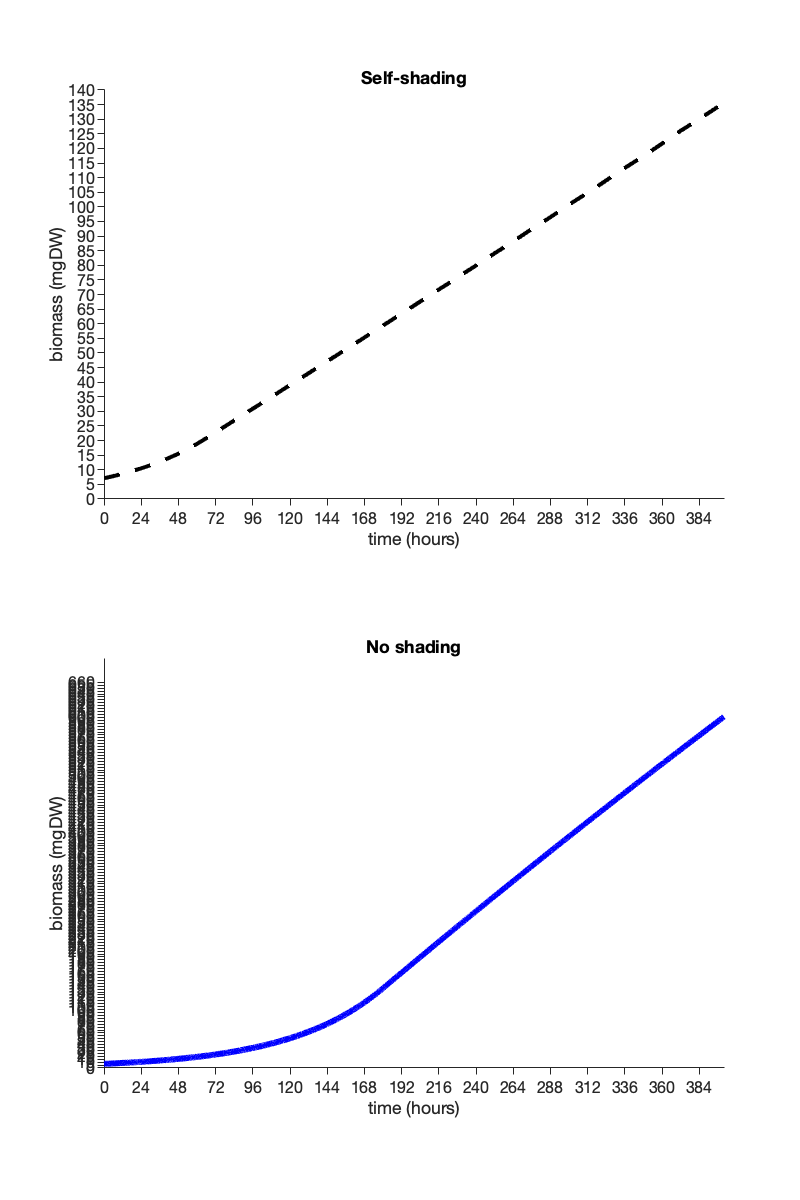


hold off

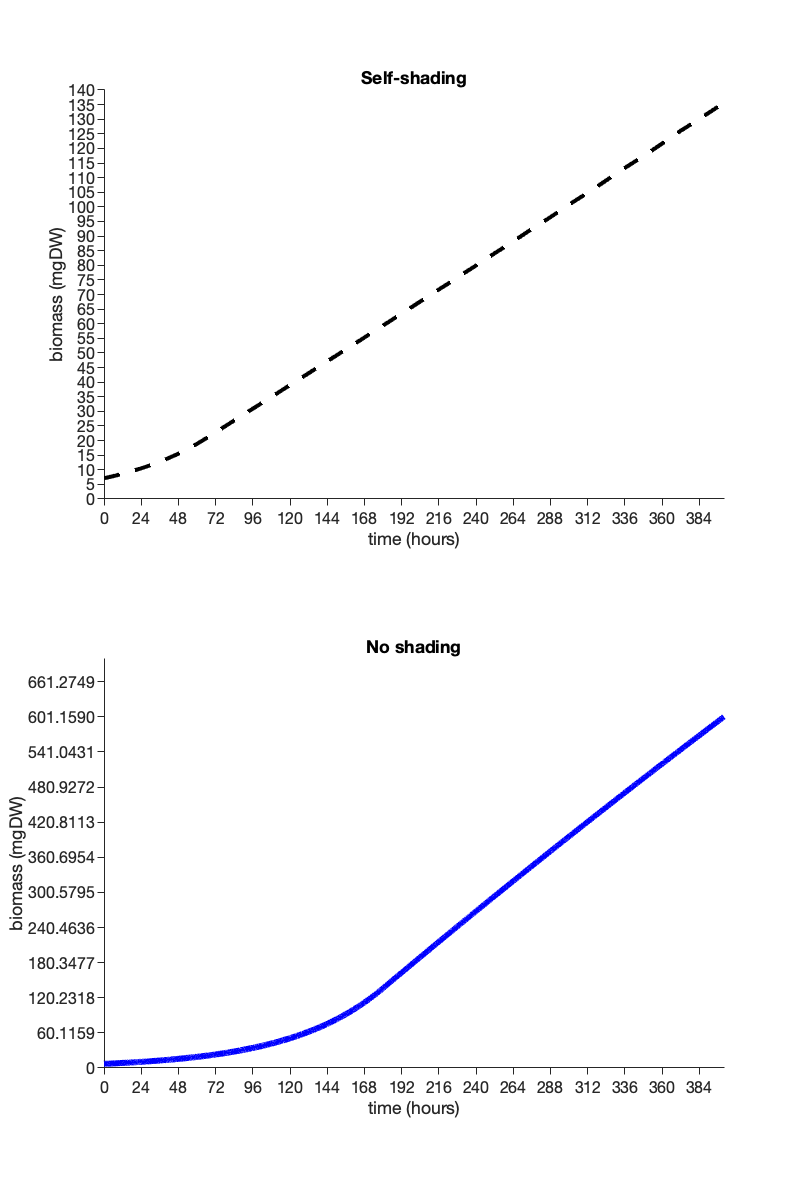

figure('position',[50 50 400 600])
% Plot self-shading
subplot(2,1,1)
hold off
plot(0:400,self1at','k--','LineWidth',2)
title('Self-shading','FontSize',12,'FontWeight','bold')
xlabel('time (hours)')
ylabel('biomass (mgDW)')
% Format
set(gca,'YTick',0:5:max(max(self1at)*1.1));
set(gca,'XTick',0:24:((length(self1at))));
set(gca,'FontSize',8)
set(gca,'Box','off');
set(gca,'TickDir','out');
% Plot no shading
subplot(2,1,2)
hold off
no_shade_x = linspace(0.1,400,4000);
no_shade_x = [0,no_shade_x];
plot(no_shade_x,results1at','b-','LineWidth',3)
title('No shading','FontSize',12,'FontWeight','bold')
xlabel('time (hours)')
ylabel('biomass (mgDW)')
% Format
set(gca,'YTick',0:(max(results1at)/10):max(max(results1at)*1.1));
set(gca,'XTick',0:24:((length(results1at)/10)));
set(gca,'FontSize',8)
set(gca,'Box','off');
set(gca,'TickDir','out');